clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;
A_JOHNogKarsten = cell(1,param.n)

A_JOHNogKarsten = 1×4 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


for i = 1:param.n
    A_JOHNogKarsten{i} = [-(param.ctrl.q_OP(i)/param.thermo.V_w(i) + param.thermo.B(i)/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i))) param.thermo.B(i)/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i)), 0;
                                param.thermo.B(i)/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i)), -(param.ctrl.Q(i)/param.thermo.V_a(i) +param.thermo.B(i)/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i))),0;
                                0, 1, 0];
end
param.model.A = blkdiag(A_JOHNogKarsten{:})

param = struct with fields:
    thermo: [1×1 struct]
      ctrl: [1×1 struct]
      pipe: [1×1 struct]
      pump: [1×1 struct]
     model: [1×1 struct]
         n: 4


eig(blkdiag(A_JOHNogKarsten{:}))

ans =          0
         0
         0
         0
   -4.0442
   -0.0312
   -0.0311
   -4.0059
   -0.0311
   -4.0059


%eig(param.model.A)



%param.model.A = -10*eye(12);
%param.model.B_Bar = blkdiag(ones(3,1),ones(3,1),ones(3,1),ones(3,1));
%param.model.B = blkdiag(ones(3,1),ones(3,1),ones(3,1),ones(3,1));
%param.model.B = ones(12,4);
%param.model.B_Bar = ones(12,4);

## Control

[param.ctrl.Ks res] = control.DesignProcedure1(param,0); 

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0449
       solvertime: 0.0021
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


LPV
eig LPV


ans = 1.0e+03 *

   -0.0010
   -0.0010
   -0.0010
   -0.0010
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


Evaluation of design procedure 1 
cali_Q is positive definite


ans =     0.3021    0.3034    0.3034    0.3034    0.7871    0.7871    0.7871    0.7884    2.0153    2.0153    2.0153    2.0161


cali_R is positive definite


ans = 1.0e-10 *

    0.0005    0.0005    0.0005    0.0005    0.0022    0.0024    0.0025    0.0026    0.1016    0.1219    0.1391    0.1421


Tau is found to be:


ans = 2.8753e-18

Eigenvalues of the decoupled systems are all negative 


ans =   -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2415 + 4.0904i  -1.2415 - 4.0904i  -0.2806 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.2654 + 6.8268i  -0.2654 - 6.8268i  -0.4921 + 6.3060i  -0.4921 - 6.3060i  -1.0512 + 4.7360i  -1.0512 - 4.7360i  -0.8367 + 5.4247i  -0.8367 - 5.4247i  -0.2776 + 0.0000i  -0.2752 + 0.0000i  -0.2724 + 0.0000i  -0.2733 + 0.0000i


eigenvalues of A


ans =          0
         0
         0
         0
   -4.0442
   -0.0312
   -0.0311
   -4.0059
   -0.0311
   -4.0059


eigenvlaues of Bk


ans =     3.2342
    2.7815
    1.6631
    2.1183
         0
         0
         0
         0
         0
         0


res = 0

%param.ctrl.Ks = control.DesignProcedure2(param,0);

%param.ctrl.Ks = control.DesignProcedureDScalingDiag(param,0);
%param.ctrl.Ks = control.DesignProcedureFunky(param,0);
%param.ctrl.Ks = control.DesignRobust(param,0

## Scaled design

yalmip('clear')   
Q = cell(1,param.n);
y = cell(1,param.n);
for i=1:param.n
    Q{i} = sdpvar(3);
    y{i} = sdpvar(3,3,'full');    
end
cali_Q = blkdiag(Q{:});
Y = blkdiag(y{:});
%Lyapuanov
constraints = [param.model.A*cali_Q+cali_Q*param.model.A.'+ Y*eye(12) + eye(12).'*Y.' <=0];
constraints = [constraints,  cali_Q >= 0];

options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints,[],options);
L = value(Y)/value(cali_Q);
K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));

Ak = param.model.A + param.model.B_Bar * K + L * eye(12);
Bk = -L;
% b1 = blkdiag([0;1;0],[0;1;0],[0;1;0],[0;1;0]);
b1 = -blkdiag([0;0;1],[0;0;1],[0;0;1],[0;0;1]);
c1 = blkdiag([0 1 0],[0 1 0],[0 1 0],[0 1 0]);

A = [param.model.A zeros(12) ; zeros(12) Ak];
B1 = [b1 ; zeros(12,4)];
B2 = [param.model.B_Bar zeros(12); zeros(12,4) Bk];
C1 = [c1 zeros(4,12)];
C2 = [zeros(4,12) K ; eye(12) zeros(12)];
D11 = zeros(4);
D12 = zeros(4,16);
D21 = zeros(16,4);
D22 = zeros(16);

ssP = [A B1 B2 ; C1 D11 D12 ; C2 D21 D22] %(3.6)

ssP =    -0.0500    0.0250         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.1296         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.9902   -3.9869         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0  

ssN11 = (A + B2/(eye(16) - D22)*C2);
ssN12 = (B1 + B2/(eye(16) - D22)*D21);
ssN21 = (C1 + D12/(eye(16) - D22)*C2);
ssN22 = (D11 + D12/(eye(16) - D22) * D21);
ssN = [ssN11, ssN12 ; ssN21, ssN22] %(3.7)

ssN =    -0.0500    0.0250         0         0         0         0         0         0         0         0         0         0    1.2795   -7.8844   -1.6823         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.9902   -3.9869         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -1.0000         0         0         0
         0         0         0   -0.0501    0.0251         0         0         0         0         0         0         0         0         0         0 


s = tf('s');
N = ssN21 / (s*eye(24) - ssN11) * ssN12 + ssN22

N =
 
  From input 1 to output...
                            2.481 s^2 + 2.498 s + 0.6294
   1:  ----------------------------------------------------------------------
       s^6 + 4.257 s^5 + 23.49 s^4 + 35.12 s^3 + 21.84 s^2 + 6.101 s + 0.6294
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
                            2.595 s^2 + 2.579 s + 0.6413
   2:  ----------------------------------------------------------------------
       s^6 + 4.264 s^5 + 23.86 s^4 + 35.78 s^3 + 22.27 s^2 + 6.219 s + 0.6413
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
                            2.552 s^2 + 2.534 s + 0.63
   3:  --------------------------------------------------------------------
       s^6 + 4.257 s^5 + 23.49 s^4 + 35.12 s^3 + 21.85 s^2 + 6.105 s + 0.63
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
                            2.532 s^2 + 2.534 s + 0.6312
   4:  -----------------------------------------------

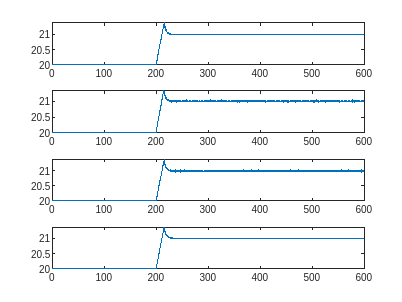

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);
coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,1)-273.15)
end